# Experimentation - Hyperparameter Tuning

In Lesson 2, we learned how to train a YOLOv8 object detection model in MATLAB. In Lesson 4, we saw how to evaluate models using metrics such as precision, recall, F1-score, and mAP. In this lesson, we will explore how to perform systematic experimentation by varying model hyperparameters and data augmentation settings to identify optimal configurations.

By the end of this session, you will be able to:

- Identify and apply** key training** and **data augmentation** hyperparameters, understanding their impact on model performance.

- Configure **MATLAB’s Experiment Manager **to run multiple trials using grid search or Bayesian optimization.

## **Recap**

In Lesson 2, we saw that the following code can be used to train a model:

In that lesson, we only worked with the `Freeze` parameter from `optionalArgs`. In this session, we will explore additional `optionalArgs`.

## Model Hyperparameters

You can find the complete list of hyperparameters, their default values, and recommendations at the following link: [Yolo hyperparameters](https://docs.ultralytics.com/usage/cfg/).

Here are some of the optional hyperparameters:

- **time** (*float*):Maximum training time in hours. If set, training will stop automatically once this time limit is reached, even if the specified number of epochs is not completed. Useful for time-constrained training.

- **optimizer** (*str*):Specifies the optimizer used during training. Common options include `'SGD'`, `'Adam'`, `'AdamW'`, `'RMSProp'`, or `'auto'` for automatic selection based on the model and task. The optimizer influences learning speed and stability.

- **lr0** (*float*):Initial learning rate controlling how fast the model updates its weights at the start of training. Choosing an appropriate value is important for effective learning.

- **lrf** (*float*):Final learning rate fraction. Defines the fraction of the initial learning rate (`lr0`) that the learning rate will decay to by the end of training, often used with learning rate schedulers.

- **momentum** (*float*):Momentum factor used by optimizers like SGD or Adam, controlling the influence of past gradients on current weight updates, which helps stabilize and speed up training.

- **batch_size **(int/ float)**: ** Batch size can be set in three ways: as an integer (e.g., batch=16) for a fixed batch size; as -1 to automatically use approximately 60% of GPU memory; or as a fraction between 0 and 1 (e.g., batch=0.70) to use that fraction of GPU memory. Batch size affects training speed and memory usage.

- **weight_decay** (*float*):L2 regularization coefficient that penalizes large model weights to reduce overfitting and improve generalization.

- **patience** (*int*):Number of epochs with no improvement in validation metrics after which training is stopped early. Helps prevent overtraining.

**Example**

## **Data augmentation hyperparameters**

So far, the hyperparameters we have defined were related to the model configuration. Next, we will explain and define the **data augmentation hyperparameters**. You can find the complete list of data augmentation hyperparameters in the following link:  [Data Augmentation Yolo](https://docs.ultralytics.com/usage/cfg/#augmentation-settings).

**Data augmentation is a fundamental technique in machine learning that artificially expands the size and diversity of a training dataset.** Its main purpose is to improve model performance, enhance generalization, and increase robustness by introducing controlled variations into the data.

In the context of YOLO models, data augmentation involves applying small transformations to the original training images to create new, slightly modified versions. These transformations help YOLO models adapt to different conditions such as changes in lighting, scale, or perspective, making them more reliable and effective in real-world scenarios.

The following list describes each augmentation parameter, its role, and its impact:

- **hsv_h **(float): Adjusts the hue of the image by a fraction of the color wheel (0.0 - 1.0). Introduces color variability to help the model generalize under different lighting conditions.

- **hsv_s **(float): Alters the saturation of the image by a fraction (0.0 - 1.0), affecting color intensity. Useful for simulating various environmental conditions.

- **hsv_v **(float): Modifies the brightness (value) of the image by a fraction (0.0 - 1.0), aiding performance under diverse lighting scenarios.

- **degrees **(float): Randomly rotates the image within a range of 0.0 to 180 degrees to improve recognition of objects in different orientations.

- **translate **(float): Shifts the image horizontally and vertically by a fraction of its size (0.0 - 1.0), helping detect partially visible or shifted objects.

- **scale **(float): Scales the image by a gain factor (≥ 0.0), simulating objects at varying distances. Default: 0.5.

- **shear **(float): Shears the image by degrees ranging from -180 to +180, mimicking different viewing angles.

- **perspective** (float): Applies random perspective distortion (0.0 - 0.001) to enhance 3D spatial understanding.

- **flipud **(float): Flips the image upside down with a given probability (0.0 - 1.0), increasing data variety without altering object traits.

- **fliplr **(float): Flips the image left to right with a probability (0.0 - 1.0), useful for learning symmetrical features and boosting dataset diversity. 

- **mosaic** (float): Combines four training images into one with a probability (0.0 - 1.0), simulating complex scenes and object interactions to improve generalization.

**Example**

## **Creating an Experiment**

To create the experiment, we will use MATLAB’s **Experiment Manager**.

For more information, see the official documentation: [Experiment Manager documentation](https://es.mathworks.com/help/matlab/ref/experimentmanager-app.html) y You can also check this example project: [Experiment Manger Example](https://es.mathworks.com/help/deeplearning/ug/custom-training-experiment-using-parallel-workers.html).

To launch the tool, we can run the following command:

experimentManager

Once the tool opens, we must create a **Blank Project** with **Custom Training**.

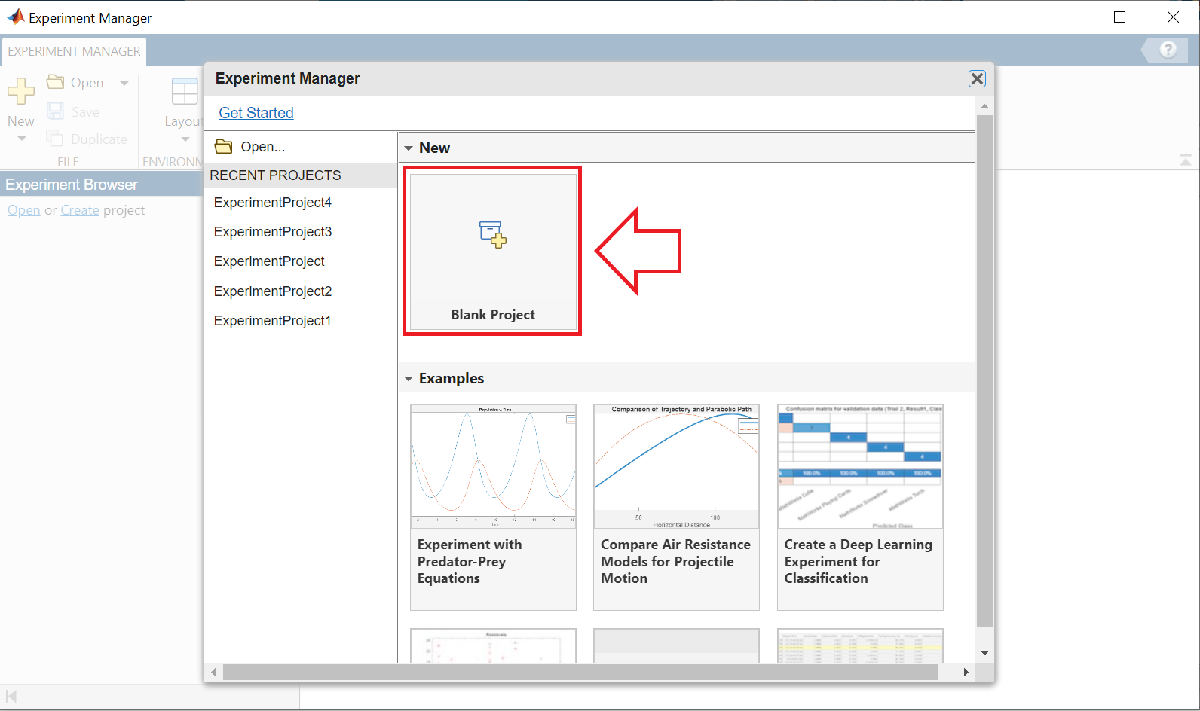

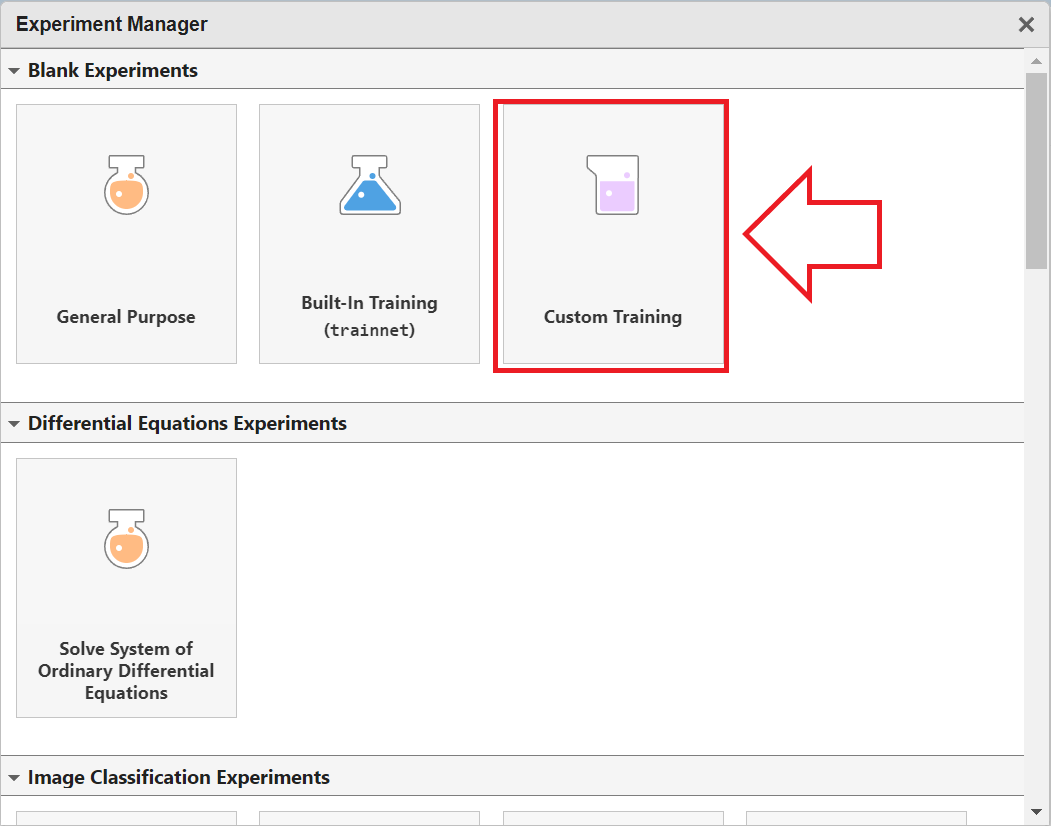

After creating the new project, you should see an interface similar to this. Click to edit the training function:

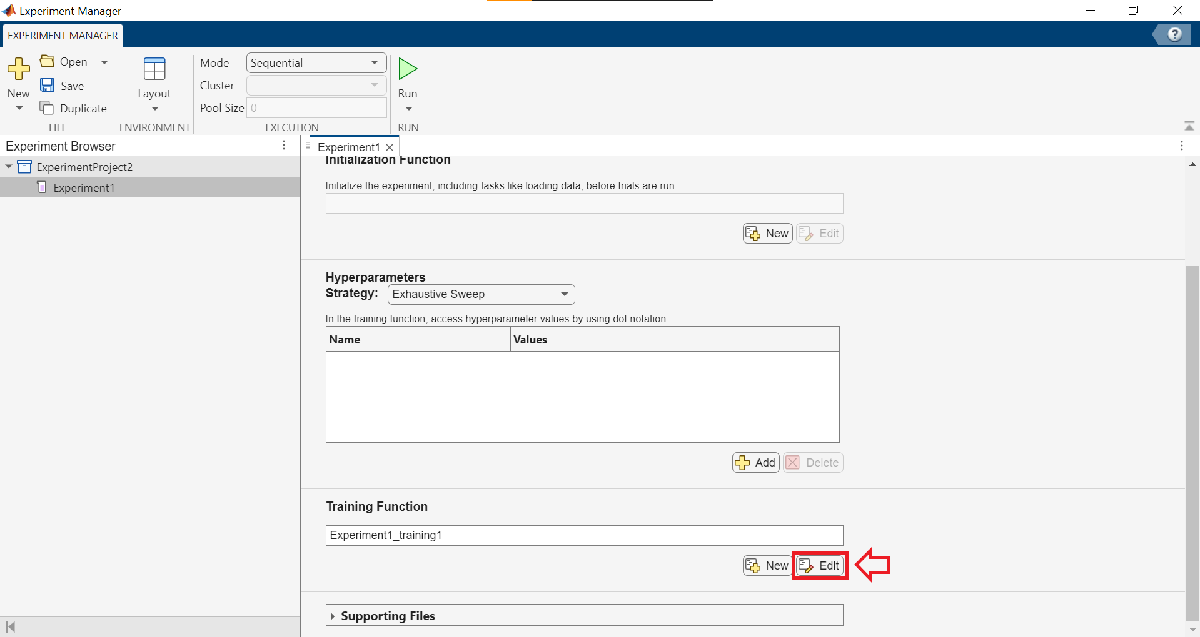

## **Define the Training Function**

Replace the existing code with this one.

The only thing you need to do is define the `workingDirectory`—you should set it to the directory where we have been working so far.

You can find your current working directory by running the command `pwd` (print working directory) in the terminal.

Additionally, you need to specify which parameters to experiment with.

In this example, we will experiment with `freeze`, `lr0`, and `lrf`.

To add more parameters, use the same format.

## **Define Hyperparameter Ranges**

Once the training function is defined, the next step is to specify the range of hyperparameters to explore. This is done within the Experiment Manager.

**Important:** The parameter names you use here must exactly match those used in the training function. For example:

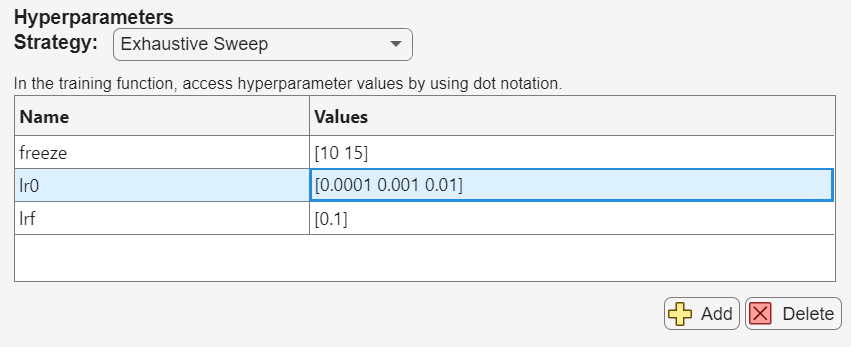

Parameter names must start with a letter, followed by letters, digits, or underscores.

Examples:

- `distance`

- `a_2`

Parameter values must be scalars or vectors. The Experiment Manager performs an exhaustive search by running a trial for every unique combination of parameter values specified in the table.

Examples:

- `0.01`

- `0.01:0.01:0.05`

- `[0.01 0.02 0.04 0.08]`

- `["alpha" "beta" "gamma"]`

**Supported data types:**

`double | single | int8 | int16 | int32 | int64 | uint8 | uint16 | uint32 | uint64 | logical | string | char`

## **Choose a Strategy**

 there are two types of strategies:

- **Exhaustive Sweep:** Runs an experiment for every possible combination of all specified hyperparameters.

- **Bayesian Optimization:** You specify hyperparameters with their value ranges and the number of iterations to run. At each iteration, the algorithm selects the most promising hyperparameter combinations based on previous results, thus avoiding the need to test the entire, often huge, parameter space.

When using Bayesian Optimization, you should specify the type of each variable, the maximum number of trials (i.e., the maximum configurations to test), and optionally, a maximum runtime. Additionally, you need to specify which metric will be used as the optimization target. This metric must be recorded during training. In our case, the recommended metric is **mAP5095**, as it accounts for both bounding box localization accuracy and class prediction correctness.

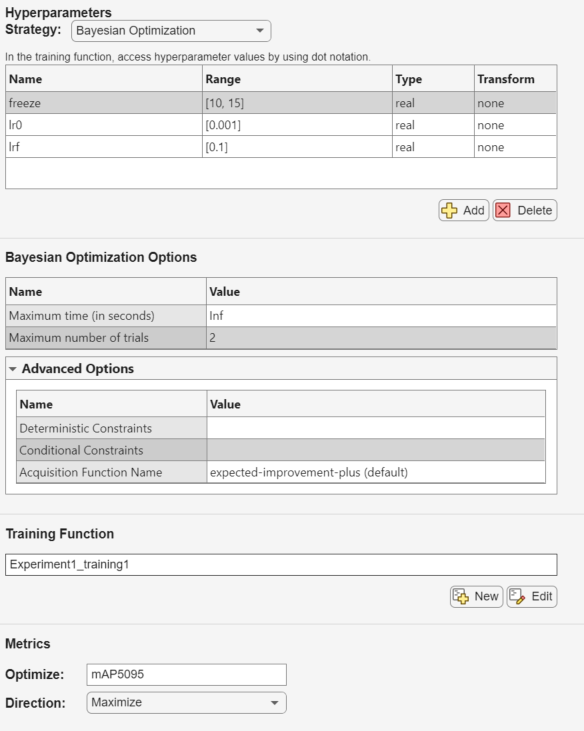

## **Run the Experiment**

Once the strategy is defined, you can click **RUN** to start the experiment.

On the training tab, after each iteration completes, you can review the metrics for that iteration.

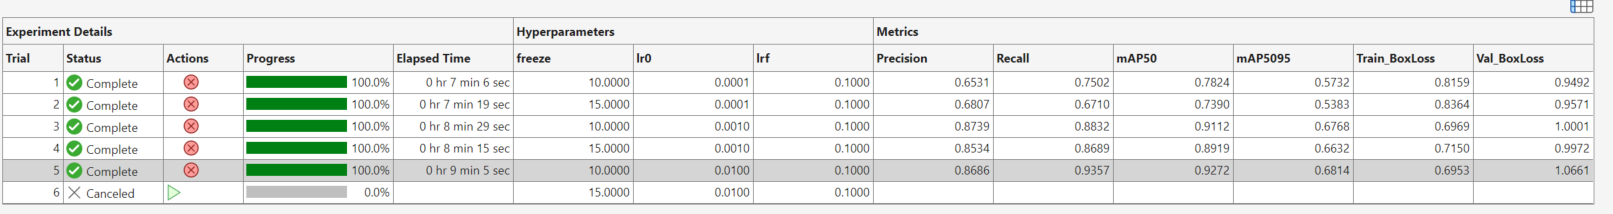

Additionally, if you click the **Training Plot** button located at the top center, a new window will open displaying plots that show the evolution of the metrics defined in the training function over the epochs for the selected trial:

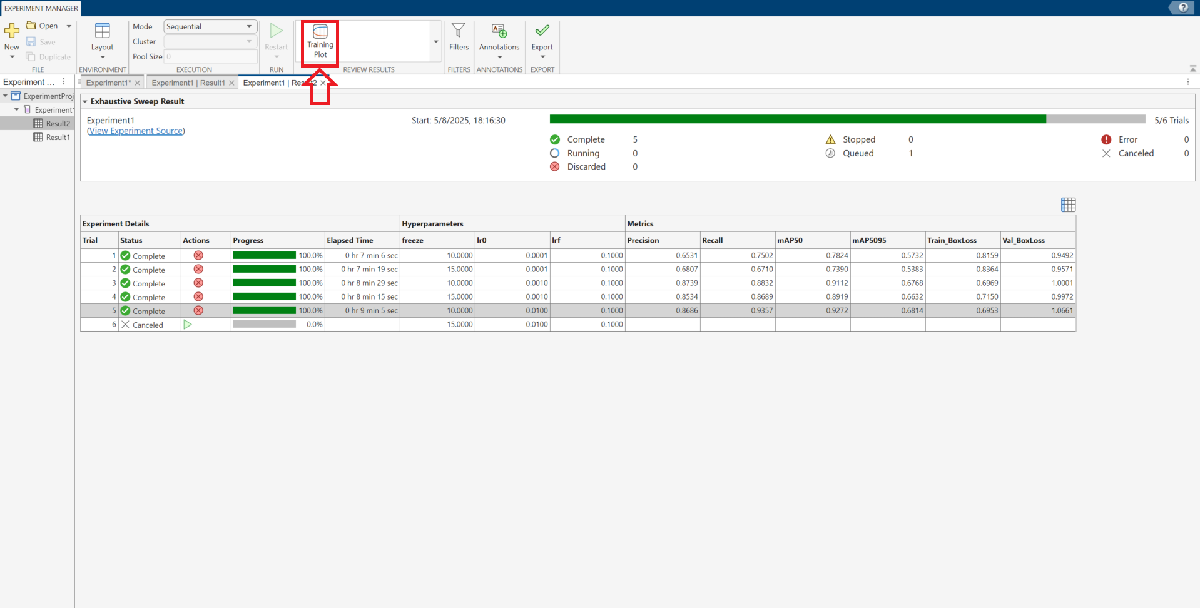

To select a trial, simply click on it in the table using your mouse.

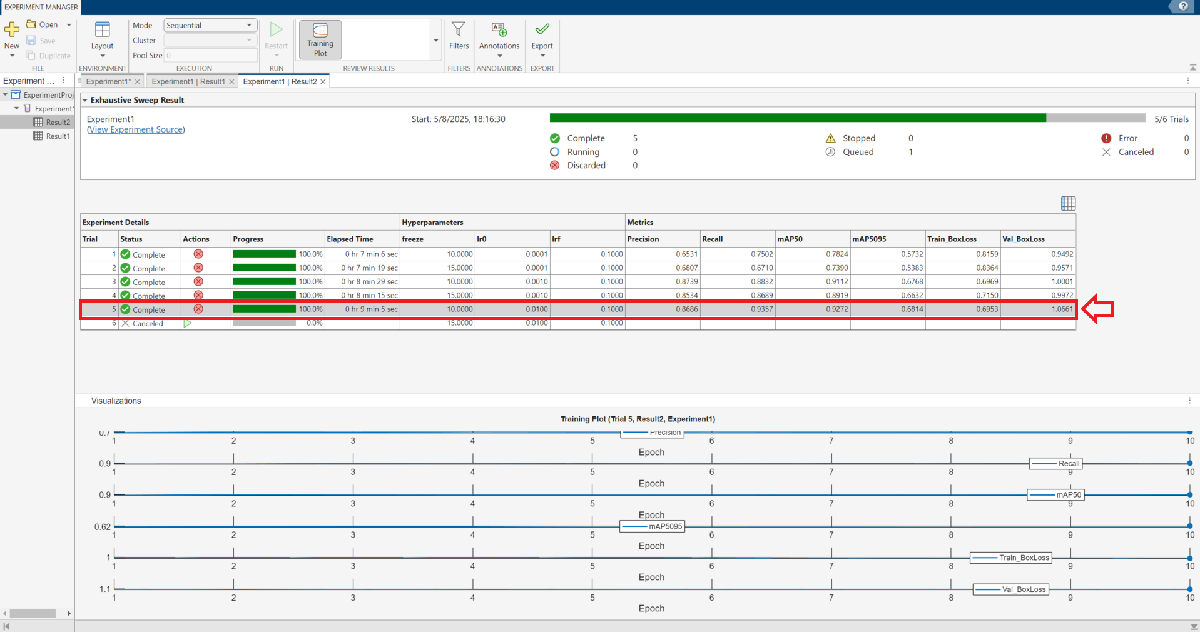

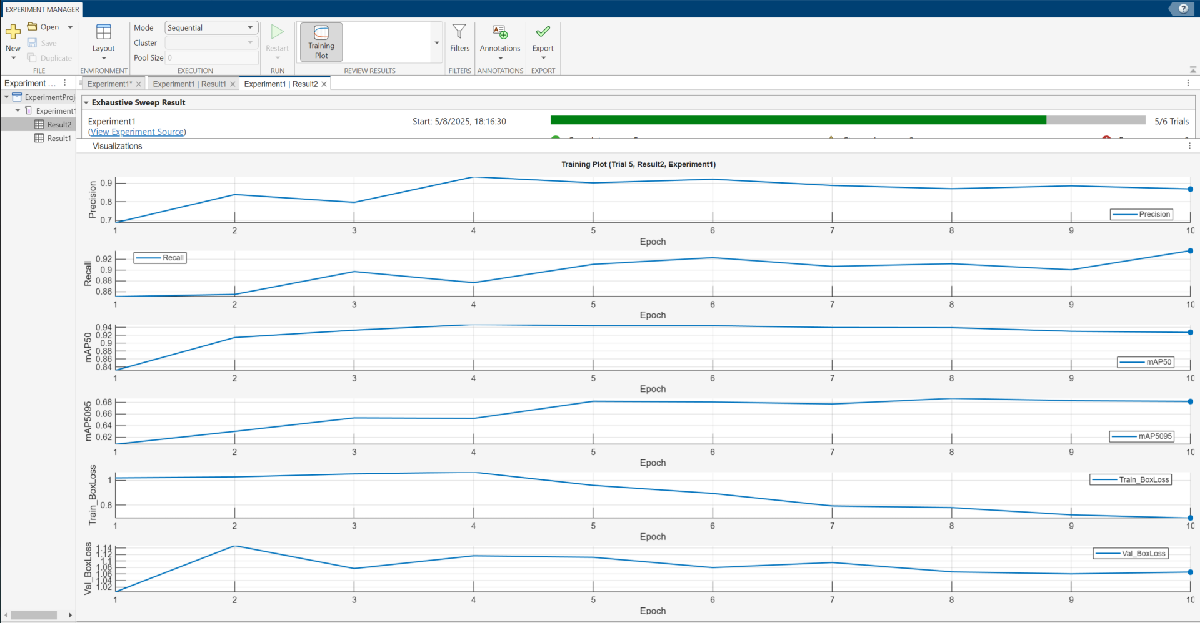

## Tensor Board

Another option to visualize the training metrics is **TensorBoard**. You can launch it using the following command, which will start a local server. Then, open your web browser and go to the following URL: [http://localhost:6006/](http://localhost:6006/)

pyInterpreter = char(getPythonInterpreter());
logdir = fullfile(pwd)

if ispc
    command = ['start "" "' pyInterpreter '" -m tensorboard.main --logdir "' logdir '"'];
else 
    command = [pyInterpreter ' -m tensorboard.main --logdir "' logdir '" &'];
end

disp(command) 
system(command); 

disp('✅ TensorBoard is running in the background (http://localhost:6006/)...');